# **batch_run_pca_temporal**

run PCA on segmented SPA EEG data, implementing ERP appropriate PCA

author: Gerardo Parra, last updated: 2023-02-21

%clear

## inputs

gp_yb = 0; % toggles settings between Gerardo and Yael 1 = Gerardo's settings, 0 = Yael's

### loading data

if gp_yb == 1
    task      = 'tss'; task_dir = get_task_path(task);
    path.tag  = '_aligned';
    path.eeg  = fullfile( 'X:','Groups','SPA','01_Data_Raw_Summary_Processed',  ...
        'EEG','Participant_Data','03_Processed_Data' );
elseif gp_yb == 0
    task      = 'ath'; %task_dir = get_task_path(task);

    task_dir = fullfile( ...
        '06_Auditory_Temporal_Habituation' )
    path.tag  = '_aligned';
    path.eeg  = fullfile( 'Z:','Groups','SPA','01_Data_Raw_Summary_Processed',  ...
        'EEG','Participant_Data','03_Processed_Data' );
end

task_dir = '06_Auditory_Temporal_Habituation'

path.task = fullfile( path.eeg,task_dir );
path.task =  'C:\Users\ch220650\Documents\02_Programming_Projects\03_BCH_Projects\Aurora_files'

path = struct with fields:
     tag: '_aligned'
     eeg: 'Z:\Groups\SPA\01_Data_Raw_Summary_Processed\EEG\Participant_Data\03_Processed_Data'
    task: 'C:\Users\ch220650\Documents\02_Programming_Projects\03_BCH_Projects\Aurora_files'
    grps: 'Z:\Groups\SPA\01_Data_Raw_Summary_Processed\EEG\Participant_Data\03_Processed_Data\01_Subject_Info_For_Processing\Group_Assignments.mat'



path.grps = fullfile( path.eeg,'01_Subject_Info_For_Processing', ...
                      'Group_Assignments.mat' );
group     = struct('name',{'TD','ASD'});

### processing params

P.chan.incl = load_1020_chans(); %1:129; %[load_1020_chans() 29 35 110 111];
excl_1020   = [9 17 22 33 45 58 70 75 83 96 108];
excl_all    = [1 125 8 14 126 127 21 25 32 128 38   ...
               43 48 44 49 56 57 63 64 68 69 73 74  ...
               81 82 88 89 94 95 99 100 107 113 114 ...
               120 119 121];
incl_other = setdiff([1:124],[excl_1020,excl_all,P.chan.incl])

incl_other =      2     3     4     5     6     7    10    12    13    15    16    18    19    20    23    26    27    28    29    30    31    34    35    37    39    40    41    42    46    47    50    51    53    54    55    59    60    61    65    66    67    71    72    76    77    78    79    80    84    85


P.chan.excl = [excl_all];%[excl_1020]; %[excl_1020 excl_all] %amp_dist
P.chan.pca  = setdiff([P.chan.incl incl_other],P.chan.excl); % channels to run PCA on
P.chan.plot = [36];       % channels to base plots on
P.t.win     = [0 400] ;%[-50 800];  % time window (ms) to use in PCA, [] to use all
P.t.rsamp   = 10;         % factor to resample time series by
P.pca.by_group = false;  % 1 = run separate PCAs by group, 0 = single PCA

## load data

[data,fpi,t,seg_win,Fs] = load_eeg_into_struct(path);

### create observation matrices

EEG = struct('eeg',[],'mean',[],'n',[]);
if P.pca.by_group
    n.group = max([data.group]);
    for i_g = 1:n.group
        % create 4d matrix: channels x samples x conditions x subjects
        EEG(i_g).ids = find([data.group]==i_g);
        A = cat(4,data(EEG(i_g).ids).eeg);
        EEG(i_g).mean = squeeze(mean(A,4));
        EEG(i_g).n = size(A,4); EEG(i_g).group = group.name{i_g};
        % prep for pca: samples x channels x subjects x conditions
        EEG(i_g).data = permute(A,[2 1 4 3]); clear A
    end
else
    % create 4d matrix: channels x samples x conditions x subjects
    A = cat(4,data.eeg); EEG.mean = squeeze(mean(A,4)); EEG.n = size(A,4);
    EEG.ids = 1:EEG.n;
    % prep for pca: samples x channels x subjects x conditions
    EEG.data = permute(A,[2 1 4 3]); EEG.group = 'all'; clear A
end
for i_g = 1:length(group), group(i_g).ids = find([data.group]==i_g); end
n.group = size(EEG,2); n.chan = size(EEG(1).mean,1);
n.samp  = size(EEG(1).mean,2); n.cond = size(EEG(1).mean,3);

## run pca

### update PCA params

if    isempty(P.t.win), P.t.ind = 1:n_samp;
else, P.t.ind = get_time_win_idxs(P.t.win,seg_win*1000,Fs);
end
P.t.n = length(P.t.ind); P.t.plot = downsample(t(P.t.ind)*1000,P.t.rsamp);
n.rsamp = ceil(P.t.n/P.t.rsamp);
P.chan.n = length(P.chan.pca); P.chan.plot_i = P.chan.pca==P.chan.plot;
chanlocs = fpi.net_vstruct(P.chan.pca);

### temporal pca

adapted from Scharf et al 2022

for i_g = 1:n.group
    % get matrix: observations x samples
    A = EEG(i_g).data(:,P.chan.pca,:,:);
    A = reshape(A,[n.samp P.chan.n*EEG(i_g).n*n.cond])';
    % get selected time window
    A = A(:,P.t.ind);
    % resample
    if P.t.rsamp > 1
        A = downsample(A',P.t.rsamp)';
    end
    % EKC
    [EKC.nF,EKC.L,EKC.refs] = myEKC(corr(A,'rows','complete'),size(A,1)); 
    EEG(i_g).ekc = EKC; clear EKC
    % run PCA
    EEG(i_g).pca = ep_doPCA( 'asis', 'Geomin', 0.01, 'SVD', 'COV',  ...
                             EEG(i_g).ekc.nF, A, 'C');
end

### reconstruct data

%% TODO: SAVE INDIVIDUAL RECONSTRUCTIONS AS MAT FILES
for i_g = 1:n.group
    nF = EEG(i_g).pca.numFacs;
    % reconstruct timeseries for each factor
    for i_f = 1:nF
        RD = EEG(i_g).pca.FacScr(:,i_f) * EEG(i_g).pca.FacPat(:,i_f)';
        dims = [n.rsamp P.chan.n EEG(i_g).n n.cond];
        RD = reshape(RD',dims); RD = permute(RD,[3 2 1 4]);
        EEG(i_g).(['r_temp' int2str(i_f)]) = RD;
    end
    
    % reshape score: subjects x channels x conds x factor
    dims = [nF P.chan.n EEG(i_g).n n.cond];
    score = EEG(i_g).pca.FacScr; score = reshape(score',dims);
    score = permute(score,[3 2 4 1]);
    for i_s = EEG.ids
        data(i_s).factor_scores = squeeze(score(i_s,:,:,:));
    end
    clear score RD
end

## plot outputs

### factor loadings

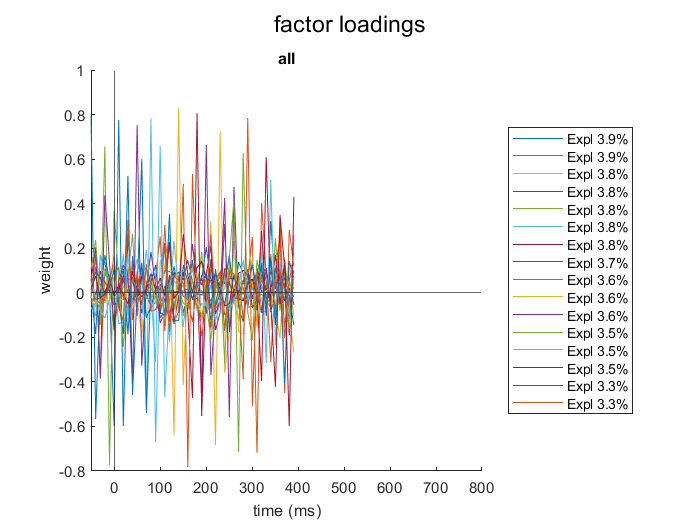

figure, sgtitle('factor loadings'), ax = zeros(1,n.group);
for i_g = 1:n.group
    ax(i_g) = subplot(n.group,1,i_g); hold on
    plot(P.t.plot,EEG(i_g).pca.FacPat), ylabel('weight') % .*EEG(i_g).pca.facVar
    % add legend
    lgnd = num2cell(EEG(i_g).pca.facVar*100); 
    lgnd = cellfun(@(x) sprintf('Expl %.1f%%',x),lgnd,'UniformOutput',false);
    xline(0,'DisplayName',''), yline(0,'DisplayName',''), title(EEG(i_g).group)
    legend(lgnd,'Location','eastoutside')
end
xlabel('time (ms)'), linkaxes(ax), xlim(P.t.win)

### reconstructed components

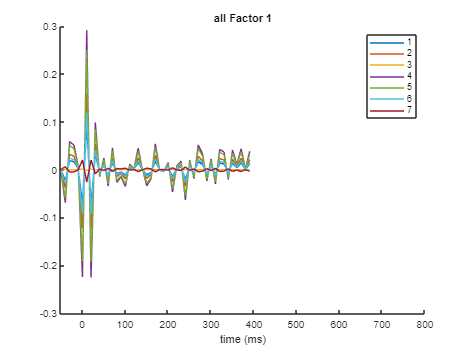

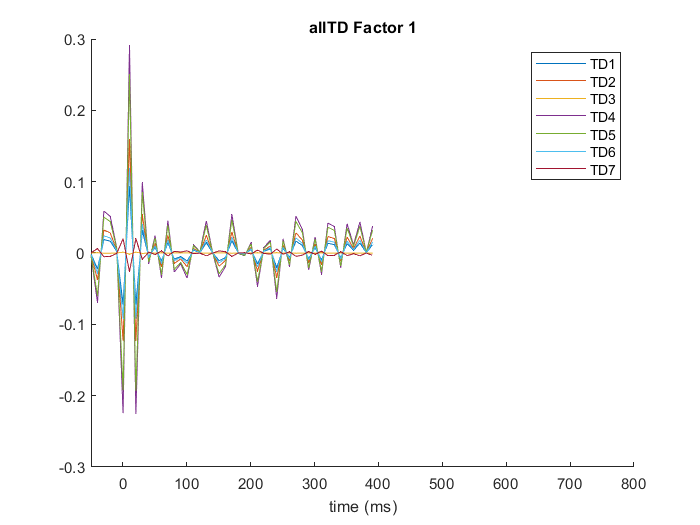

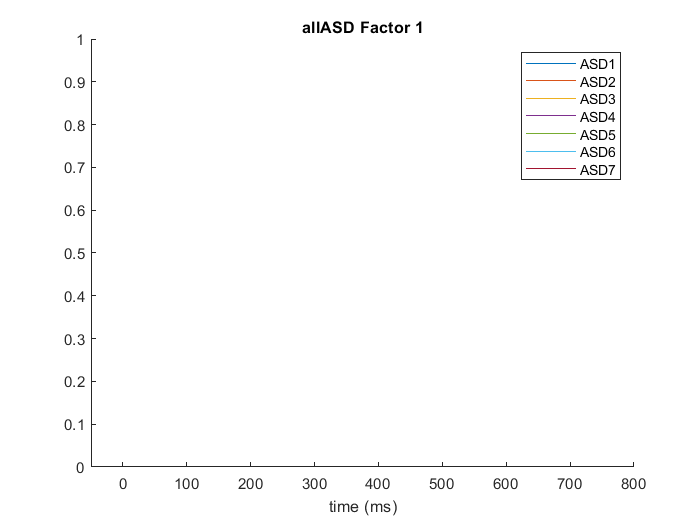

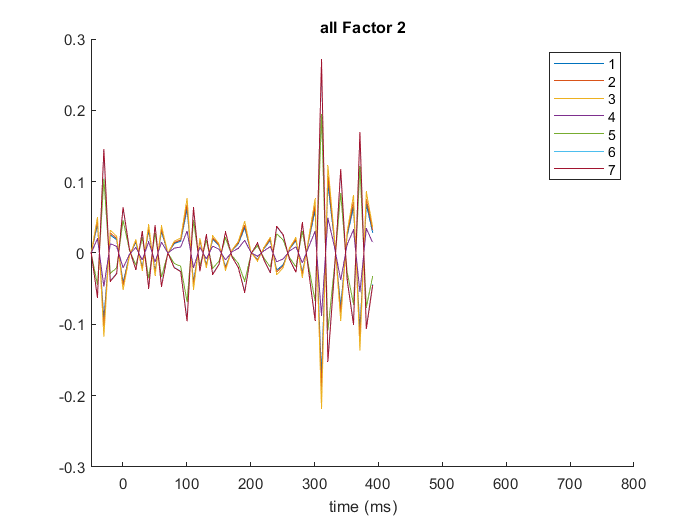

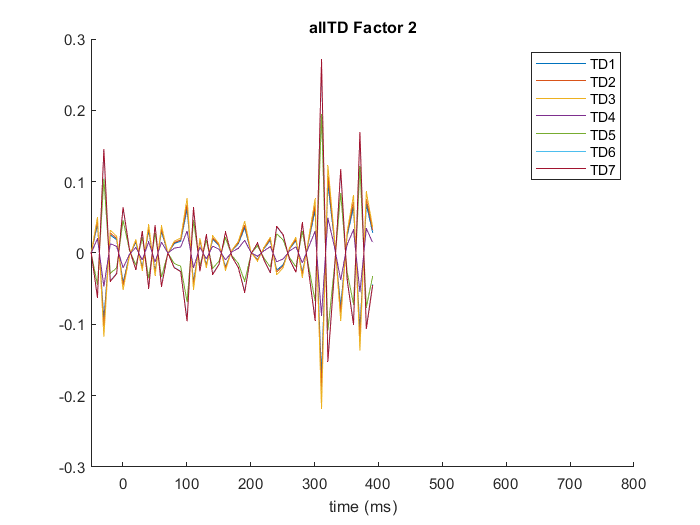

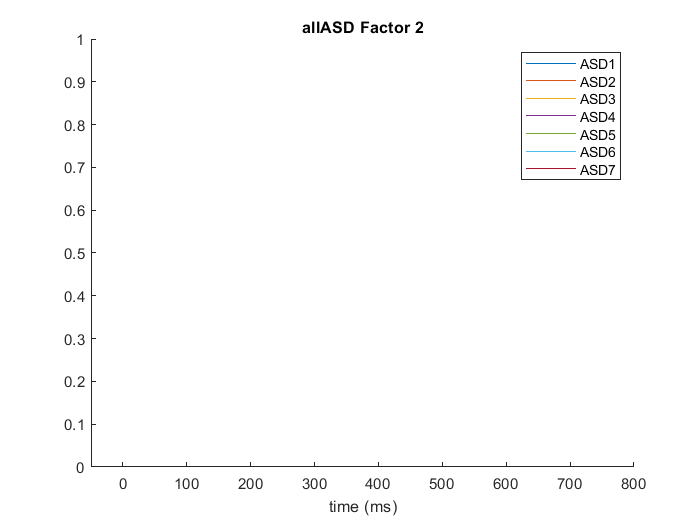

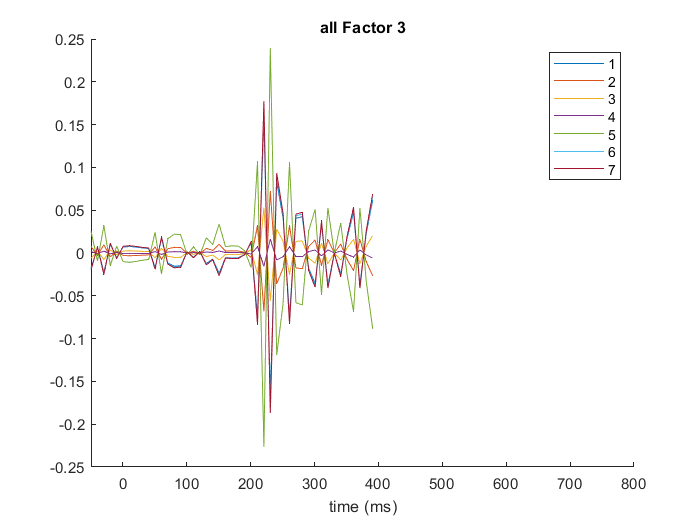

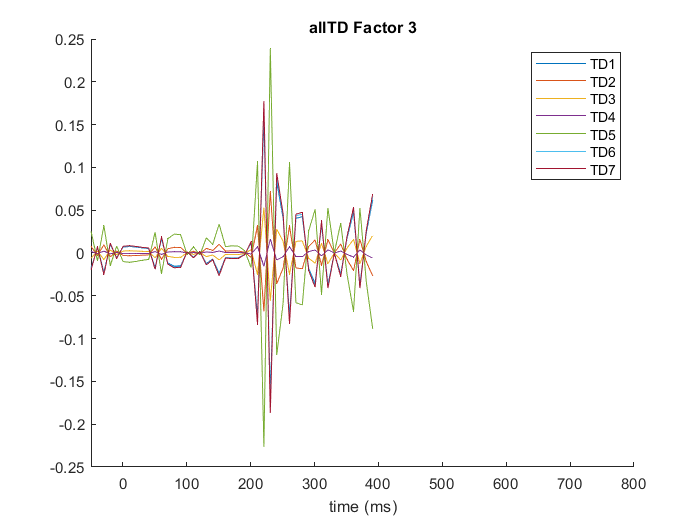


for i_g = 1:n.group

    for i_f = 1:EEG(i_g).pca.numFacs
        for sub_group_plot = 1:[n.group + length(group)]
            if ~P.pca.by_group && sub_group_plot >1
                sub_idxs = find([data.group] == sub_group_plot-1); tit = group(sub_group_plot-1).name;
            else
                sub_idxs = 1:length(data); tit = '';
            end
            facName = ['r_temp' int2str(i_f)];
            figure, hold on, title([EEG(i_g).group tit ' Factor ' int2str(i_f)])
            comp = EEG(i_g).(facName)(sub_idxs,P.chan.plot_i,:,:);
            comp = squeeze(mean(comp,1));
            for cond = 1:size(comp,2)
                plot(P.t.plot,comp(:,cond),'DisplayName',[tit num2str(cond)])
                hold on
            end
            legend
            xlabel('time (ms)'), xlim(P.t.win)
        end
    end
end

### factor scores by group

% sort factor scores by group and factor
scores = cell(length(group),nF);
for i_g = 1:length(group)
    grp_scores = cat(4,data(group(i_g).ids).factor_scores);
    grp_scores = permute(grp_scores,[4 1 2 3]);
    for i_f = 1:nF
        scores{i_g,i_f} = squeeze(grp_scores(:,:,:,i_f));
    end
    clear grp_scores
end

Index in position 4 exceeds array bounds. Index must not exceed 1.


% plot factor scores by factor
for i_f = 1:nF
    figure, sgtitle(['Standardized Factor ' int2str(i_f) ' scores'])
    ax = zeros(1,length(group));
    for i_g = 1:length(group)
        ax(i_g) = subplot(1,length(group),i_g); hold on
        % to do: plot sum/avg across all channels?
        grp_scores = squeeze(scores{i_g,i_f}(:,P.chan.plot_i,:));
        plotSpread(grp_scores,'showMM',3), title(group(i_g).name), clear grp_scores
    end
    linkaxes(ax)
end

### suppression (from factor scores)

if strcmp(task,'TSS')
for i_f = 1:nF
    figure, sgtitle(['Suppression: Factor ' int2str(i_f)])
    for i_g = 1:length(group)
        grsc = squeeze(scores{i_g,i_f}(:,P.chan.plot_i,:));
        suppression{i_g} = (grsc(:,1)+grsc(:,2)-grsc(:,3))./(grsc(:,1)+grsc(:,2));
    end
    plotSpread(suppression,'showMM',3)
    yline([0 1],'--'), ylim([-5 5]), xticklabels({group.name})
end
end

### reconstructed topography


for i_g = 1:n.group
    for i_f = 1:EEG(i_g).pca.numFacs
        for sub_group_plot = 1:[n.group + length(group)]
            if ~P.pca.by_group && sub_group_plot >1
                sub_idxs = find([data.group] == sub_group_plot-1); tit = group(sub_group_plot-1).name;
            else
                sub_idxs = 1:length(data); tit = '';
            end
            fac_idx = find(EEG(i_g).pca.FacPat(:,i_f) == max(EEG(i_g).pca.FacPat(:,i_f)))
            facName = ['r_temp' int2str(i_f)];
            figure, hold on, sgtitle([EEG(i_g).group tit ' Factor ' int2str(i_f)])
            comp = mean( EEG(i_g).(facName)(sub_idxs,:,[fac_idx-2:fac_idx+2],:), 3 ); % temporal average
            comp = squeeze(nanmean(comp,1)); % subject average
            for i_c = 1:n.cond
                subplot(1,n.cond,i_c), hold on
                topoplot(comp(:,i_c),chanlocs);
            end
        end
    end
end